# Forward Kinematics of the Stewart Platform

## Input

% Lengths of the legs (Input) in mm
leg_lengths = [180.724259518072,180.546310004650,181.514478467853,180.852854760103,181.048878255403,180.468455208287];    

## Data


R1=130/2; % radius of the Fixed Platform in mm
R2=125/2; % radius of the Moving Platform in mmm
GAMMA=20; % half angle between to adjacent legs in Degree
    
% Define the fixed and moving platform geometry

        % % Theoretical Fixed platform leg points
        % B1=[R1*cosd(60-GAMMA) R1*sind(60-GAMMA) 0]'; 
        % B2=[R1*cosd(60+GAMMA) R1*sind(60+GAMMA) 0]'; 
        % B3=[-R1*cosd(GAMMA) R1*sind(GAMMA) 0]'; 
        % B4=[-R1*cosd(GAMMA) -R1*sind(GAMMA) 0]'; 
        % B5=[R1*cosd(60+GAMMA) -R1*sind(60+GAMMA) 0]'; 
        % B6=[R1*cosd(60-GAMMA) -R1*sind(60-GAMMA) 0]'; 

        % B = [B1 B2 B3 B4 B5 B6];

% Actual Fixed platform legs points
B1=[49.834,41.765,-10.52+11]'; 
B2=[11.327,63.988,-10.504+11]'; 
B3=[-61.058, 22.228,-10.654+11]'; 
B4=[-61.06,-22.233,-10.803+11]'; 
B5=[11.3,-64.009,-10.898+11]'; 
B6=[49.825,-41.784,-10.779+11]'; 

B = [B1 B2 B3 B4 B5 B6];  

        % % Theoretical Moving platform legs points
        % P1=[R2*cosd(GAMMA) R2*sind(GAMMA) 0]';
        % P2=[-R2*sind(30-GAMMA) R2*cosd(30-GAMMA) 0]';
        % P3=[-R2*sind(30+GAMMA) R2*cosd(30+GAMMA) 0]';
        % P4=[-R2*sind(30+GAMMA) -R2*cosd(30+GAMMA) 0]';
        % P5=[-R2*sind(30-GAMMA) -R2*cosd(30-GAMMA) 0]';
        % P6=[R2*cosd(GAMMA) -R2*sind(GAMMA) 0]';
     
        % P = [P1 P2 P3 P4 P5 P6];

% Actual Moving platform legs points
P1=[58.708,21.383,-11.171+11]';
P2=[-10.875,61.556,-10.94+11]';
P3=[-47.912,40.187,-10.888+11]';
P4=[-47.907,-40.162,-11.017+11]';
P5=[-10.873,-61.536,-11.135+11]';
P6=[58.704,-21.364,-11.243+11]';

P = [P1 P2 P3 P4 P5 P6];

## Output

x = stewart_forward_kinematics(B,P,leg_lengths);


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          7             6.43212                            23.7              1
     1         14            0.745336              1             2.65              1
     2         21         1.82527e-05       0.514502            0.243            2.5
     3         28         1.94636e-15     0.00163367         4.49e-06            2.5
     4         35         3.23117e-27    2.03222e-08         2.37e-12            2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as me

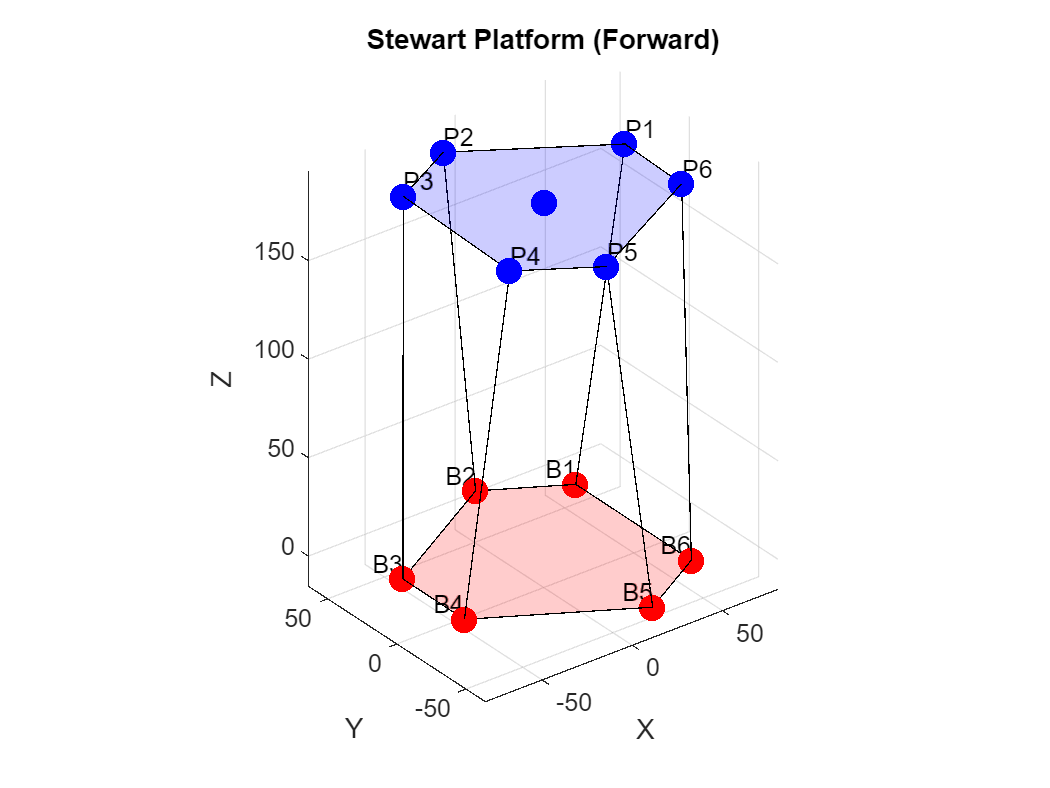

% Plot the Stewart platform in 3D
[R, P_global, top_centre] = plot_stewart_platform(x, B, P);

## Functions

### Function of Non-linear Minimization solver

function [x] = stewart_forward_kinematics(B,P,leg_lengths)
     
    % Initial guess for platform position and orientation (x, y, z, roll, pitch, yaw)
    x0 = [0, 0, mean(leg_lengths), 0, 0, 0];
    
    % Solve for the position and orientation 

    % using fsolve (non linear solver)
    options = optimoptions('fsolve', 'Display', 'iter','FunctionTolerance',10^-9);
    % options = optimoptions('fsolve', 'Display', 'none','FunctionTolerance',10^-9);
    % options = optimoptions('fsolve','Display', 'none');

    %[x, fval, exitflag] = fsolve(@(x) kinematic_equations(x, B, P, leg_lengths), x0, options);
    x = fsolve(@(x) kinematic_equations(x, B, P, leg_lengths), x0, options);
    
    % Print the result on display
    fprintf('Position of the platform (mm):\n');
    fprintf('\tx: %.6f\n', x(1));
    fprintf('\ty: %.6f\n', x(2));
    fprintf('\tz: %.6f\n', x(3));
    fprintf('orientation of the platform (degree):\n');
    fprintf('\troll: %.6f\n', rad2deg(x(4)));
    fprintf('\tpitch: %.6f\n', rad2deg(x(5)));
    fprintf('\tyaw: %.6f\n', rad2deg(x(6)));

end

### Function to Calculate Position and orientation

function F = kinematic_equations(x, B, P, leg_lengths)
    % Extract position and orientation from x
    px = x(1);
    py = x(2);
    pz = x(3);
    roll = x(4);
    pitch = x(5);
    yaw = x(6);
    
    % Rotation matrix from roll, pitch, yaw
    % R = eul2rotm([yaw, pitch, roll]); % Traditional method
    R = Eul2rotm([roll, pitch, yaw]);
    
    
    % Compute the equations for each leg
    F = zeros(6, 1);
    for i = 1:6
        % Platform attachment point in global frame
        p_global = [px; py; pz] + R * P(:, i);
        
        % Compute the distance between base and platform attachment points
        d = norm(p_global - B(:, i));
       
        % error (computed leg length - actual leg_length)
        F(i) = d - leg_lengths(i);
    end
    
end

### Function to create Rotational Matrix from Euler angles

% Traditional 
    % function R = eul2rotm(eul)
    %     % Convert Euler angles to rotation matrix
    %     % eul = [yaw, pitch, roll]
    %     yaw = eul(1);
    %     pitch = eul(2);
    %     roll = eul(3);
    % 
    %     % Rotation matrix around z-axis (yaw)
    %     Rz = [cos(yaw), -sin(yaw), 0;
    %           sin(yaw),  cos(yaw), 0;
    %           0,        0,       1];
    % 
    %     % Rotation matrix around y-axis (pitch)
    %     Ry = [cos(pitch), 0, sin(pitch);
    %           0,          1, 0;
    %           -sin(pitch), 0, cos(pitch)];
    % 
    %     % Rotation matrix around x-axis (roll)
    %     Rx = [1, 0,       0;
    %           0, cos(roll), -sin(roll);
    %           0, sin(roll),  cos(roll)];
    % 
    %     % Combined rotation matrix
    %     R = Rz * Ry * Rx;
    % end

function R = Eul2rotm(eul)
    % Euler angles are in the order of [roll, pitch, yaw]
    R = eul2rotm([eul(1), eul(2), eul(3)],"XYZ");
end

### Function to Plot

function [R, P_global, top_centre] = plot_stewart_platform(x, B, P)
    % Extract position and orientation
    px = x(1);
    py = x(2);
    pz = x(3);
    roll = x(4);
    pitch = x(5);
    yaw = x(6);
    
    % Rotation matrix from roll, pitch, yaw
    R = Eul2rotm([roll, pitch,yaw]);
    
    % Compute the platform attachment points in the global frame
    P_global = [px; py; pz] + R * P;
    
    % Plot the base attachment points
    figure;
    hold on;
    plot3(B(1,:), B(2,:), B(3,:), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    hold on
    fill3(B(1,:), B(2,:), B(3,:),'r', 'FaceAlpha', 0.2);
    text(B(1,:), B(2,:), B(3,:), {'B1', 'B2', 'B3', 'B4', 'B5', 'B6'},'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

    % Plot the platform attachment points
    plot3(P_global(1,:), P_global(2,:), P_global(3,:), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    hold on
    fill3(P_global(1,:), P_global(2,:), P_global(3,:),'b','FaceAlpha', 0.2);
    text(P_global(1,:), P_global(2,:), P_global(3,:), {'P1', 'P2', 'P3', 'P4', 'P5', 'P6'},'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');

    % Plot the legs
    for i = 1:6
        plot3([B(1,i), P_global(1,i)], [B(2,i), P_global(2,i)], [B(3,i), P_global(3,i)], 'k-');
    end

    % Plot Centre
    top_centre = mean(P_global,2);
    plot3(top_centre(1),top_centre(2),top_centre(3),'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    
    % Plot settings
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Stewart Platform (Forward)');
    grid on;
    axis equal;
    view(3);
    hold off;

end

## Reference Diagram